# Visualize Flow Data Using Streamline Plots

Streamline plots create lines that indicate the direction of flow in a volume visualization.

### Read Wind Data

We will use `wind.mat` to demonstrate how to create and customize streamline plots. This contains sample data that represents air currents over North America. Use a helper function to extract a subset of the data for visualization.

[X,Y,U,V] = readWindData;

### Basic 2-D Streamline Plot

Visualize a subset of the air current data. Use a helper function to obtain the start coordinates of the streamlines and specify them as the 5th and 6th input arguments to `streamline`.

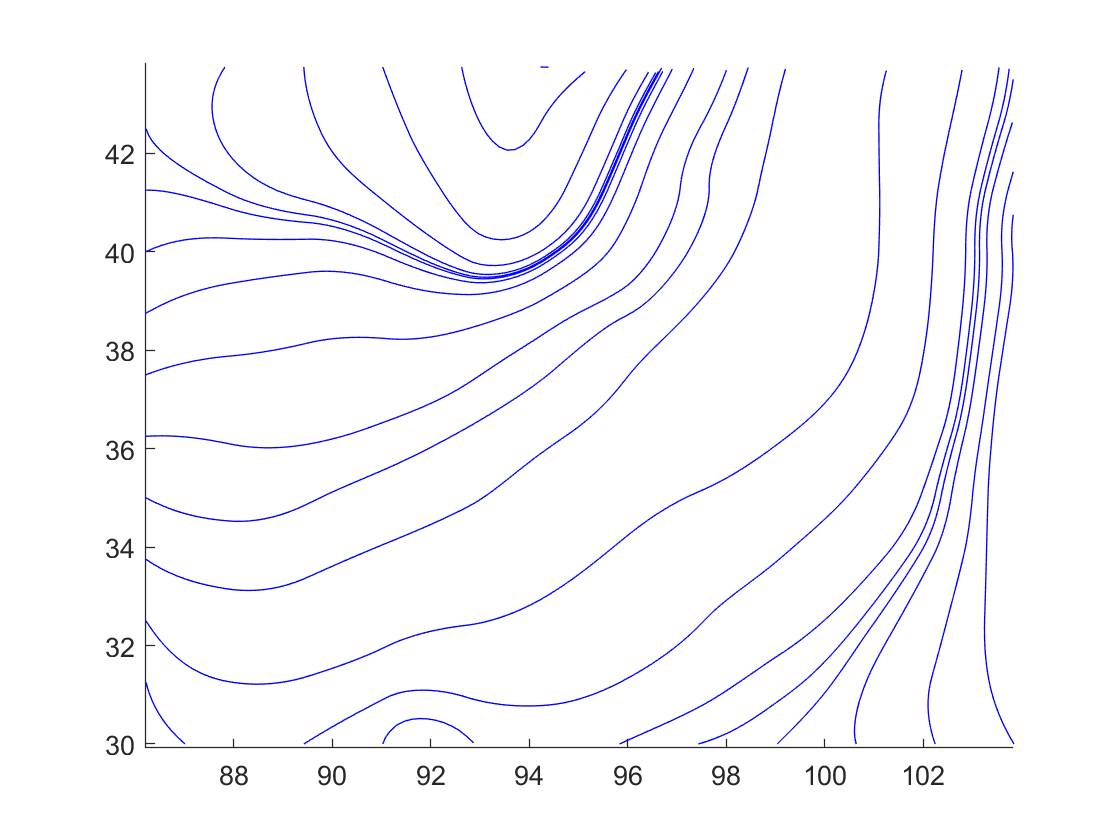

[xstart, ystart] = getStartCoordinates(X,Y);
streamline(X,Y,U,V,xstart, ystart);
axis equal

### Basic 3-D Streamline Plot

Visualize all the air current data. Use `meshgrid` to create arrays representing the start coordinates of the 3-D streamlines. Visualize the streamlines from a 3-D perspective using `view`.

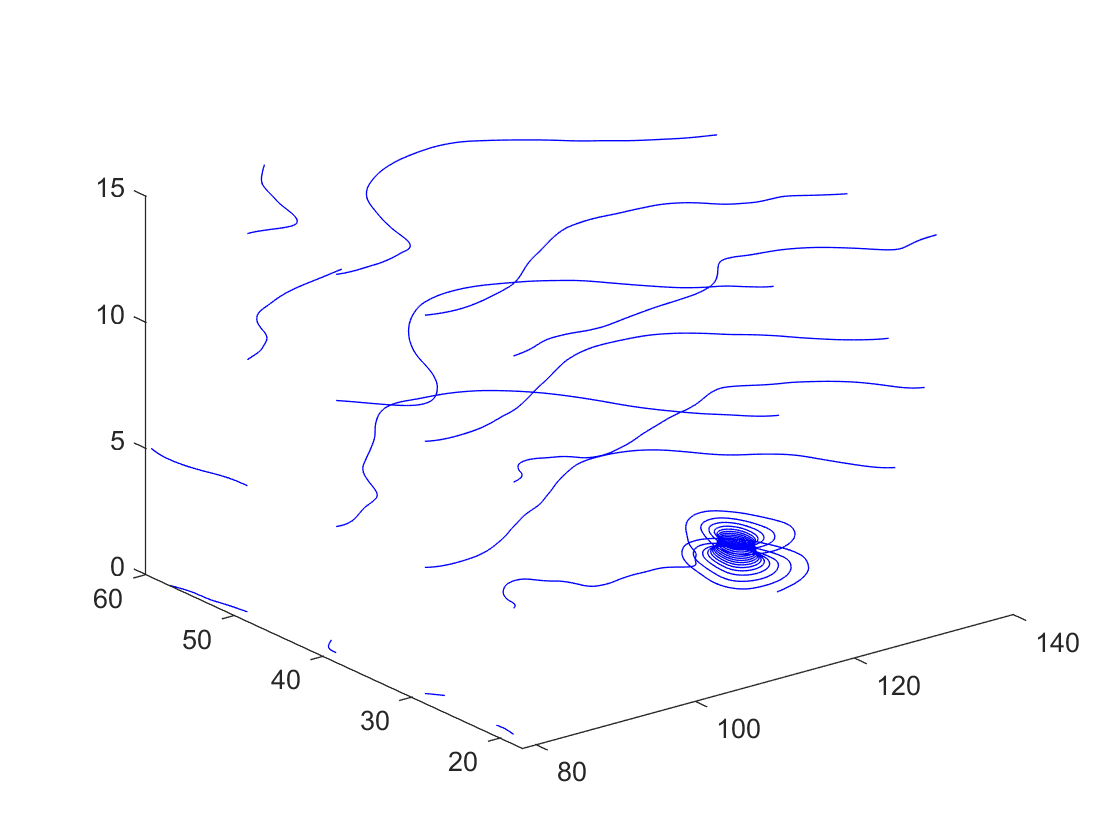

[xstart2, ystart2, zstart2] = meshgrid(80,20:10:50,0:5:15);

figure()
streamline(x,y,z,u,v,w,xstart2, ystart2, zstart2);
view(3)

## Customization

### Add a Quiver Plot

The quiver plot arrows help clarify flow direction. Use *hold on *to plot the quiver arrows on the same plot as the streamlines.

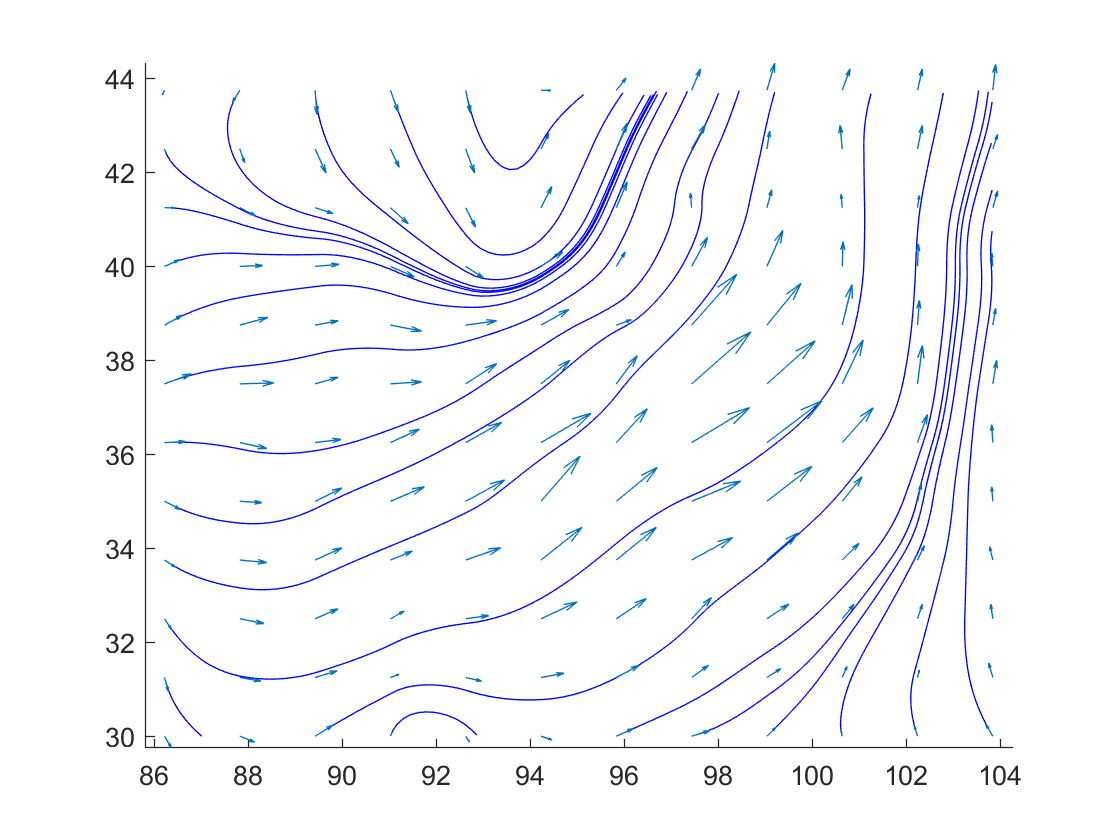

figure
s = streamline(X,Y,U,V,xstart,ystart);
hold on
q = quiver(X,Y,U,V);
axis equal

### Specify Line Color and Width

Use the `set` function to set the line color and width of streamlines using Name, Value pair arguments.

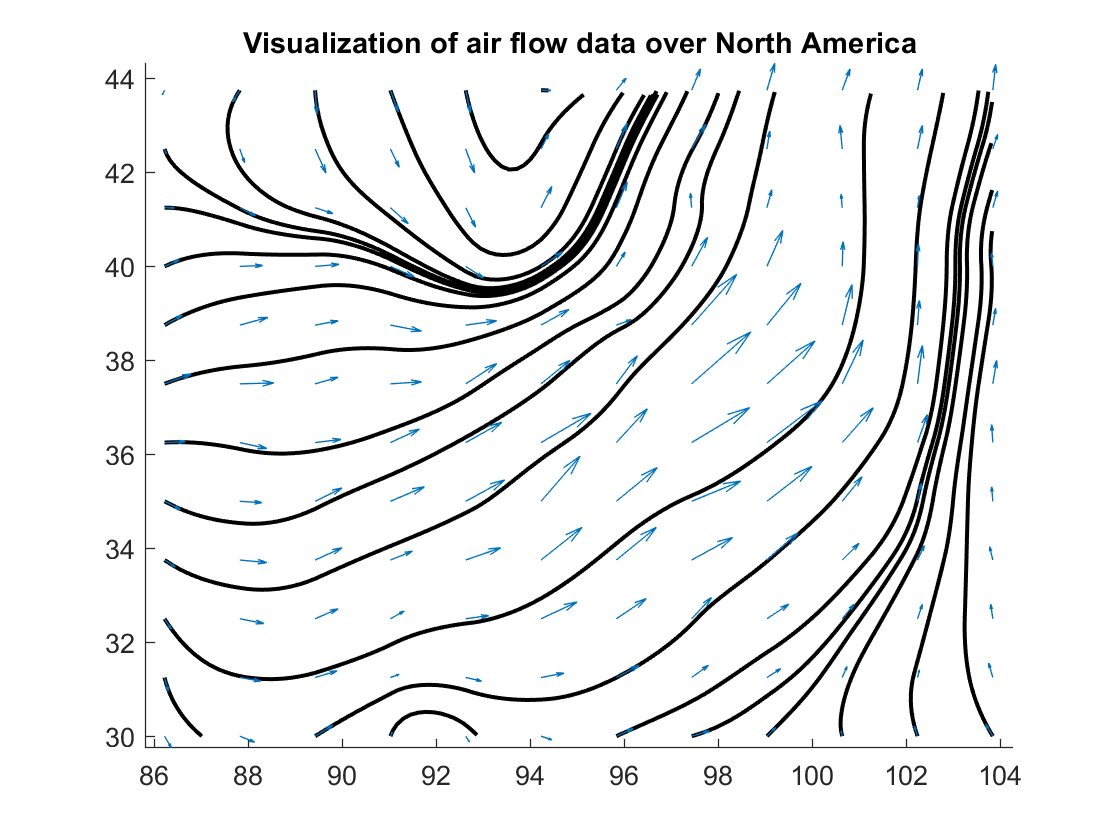

LineColor = 'k';
LineWidth = 1.5;

set(s,...                   % Specify the plot handle
    "Color",LineColor,...   % Specify the line color
    "LineWidth",LineWidth); % Specify the line width
title("Visualization of air flow data over North America")

## **Additional Information**

### **Get All Line Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Line, uncomment the following code. View or modify these properties using dot notation.

% get(s(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[streamline](https://www.mathworks.com/help/matlab/ref/streamline.html)

### Helper Functions

This helper function uses the data to generate starting coordinates for 2-D streamlines.

function [xstart, ystart] = getStartCoordinates(X,Y)
    xstart = [X(:,1) X(end,:)' X(1,:)'];
    ystart = [Y(:,1) Y(end,:)' Y(1,:)'];
end

This helper function reads in wind data, and extracts a subset of the data into variables X, Y, U and V.

function [X,Y,U,V] = readWindData()
    load wind
    X = x(11:22,11:22,1);
    Y = y(11:22,11:22,1);
    U = u(11:22,11:22,1);
    V = v(11:22,11:22,1);
end

Copyright (c) 2021, The MathWorks, Inc.